clear
close all

p = 8; % patch size
M = p^2; % number of element in the patch

% load the cameraman image
img = im2double(imread('sample_text.png'));

% compute the DCT dictionary (use the method you prefer to compute the 2D DCT)
% Here we use the separable way
% The separable way is more convenient because it allowes to compute
% just p*p elements instead of M*M

D = zeros(p);
for ii = 1:p
    a = zeros(1, p);
    a(ii) = 1;
    D(:, ii) = idct(a)';
end %correct

% set the threshold for the compression
threshold = 0.1;

% initialize the compressed image
sizes = size(img);
img_comp = zeros(sizes);

% initliaze the number of nonzero coefficients
nnz_coeff = 0;

% process the image patchwise
for ii=1:p:size(img, 1)
    for jj=1:p:size(img, 2)
        
        % extract the patch
        s = img(ii:ii+7, jj:jj+7);
        
        % compute the representation w.r.t. the 2D DCT dictionary
        x = D' * s * D;
        
        % perform the hard thresholding (do not perform HT on the DC!)
        
        x_HT = (abs(x)>threshold).*x;
        if x_HT(1) == 0 
            x_HT(1) = x(1);
        end
        
        
        % reconstruct the patch
        s_hat = D * x_HT * D';
        
        % put the compressed patch in the compressed image
        img_comp(ii:ii+p-1, jj:jj+p-1) = s_hat;
        
        % update the total number of nonzero coefficients
        nnz_coeff = nnz_coeff + sum(abs(x)>threshold, 'all');
    end
end

% compute the psnr
psnr = 10 * log10(sizes(1)*sizes(2)/(sum((img_comp - img).^2, 'all')))

psnr = 31.8561


% compute the compression ratio
comp_ration = nnz_coeff / (256*256)

comp_ration = 0.0674

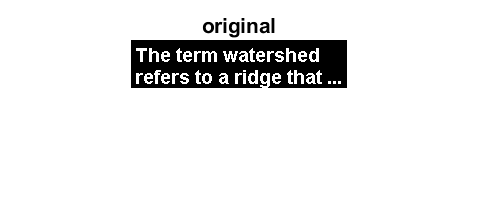


% show the original and the compressed images
figure(2)
imshow(img, [])
title('original')

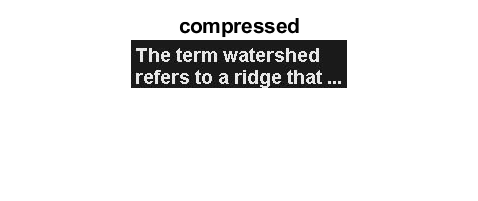


figure(3)
imshow(img_comp,[])
title('compressed')


% the higher the threshold the bigger the compression.

% Regarding the cameraman image:
% Using a small threshold like 0.1 lead to a comp_ratio of 0.1
% so we need to store just 10% of the initial image. We loose
% just small details (look at the hand of the guy or at the grass).